dt = 0.1;
time = 0:dt:50;

%System parameters
a = 0.1;
b = 0.5;
T_env = 25;
T = 25;

setpoint = 60;

%Storage
temps_no_control = zeros(size(time));

for i = 1:length(time)
    u = 10;
    
    dTdt = -a*(T - T_env) + b*u;
    T = T + dTdt * dt;

    temps_no_control(i) = T;
end 

T = 25;
temps_pid = zeros(size(time));

%PID gains
Kp = 2.0;
Ki = 0.2;
Kd = 1.0;

%PID variables
integral = 0;
prev_error = 0;

for i = 1:length(time)
    error = setpoint - T;
    integral = integral + error * dt;
    if i == 1
        derivative = 0;
    else
        derivative = (error - prev_error) / dt;
    end
    
    u = Kp*error + Ki*integral + Kd*derivative;
    u = max(0, min(100,u));

    temps_pid(i) = T;

    %System dynamics
    dTdt = -a*(T - T_env) + b*u;
    T = T + dTdt * dt;
    
    prev_error = error;
end
disp(T)

   60.0129



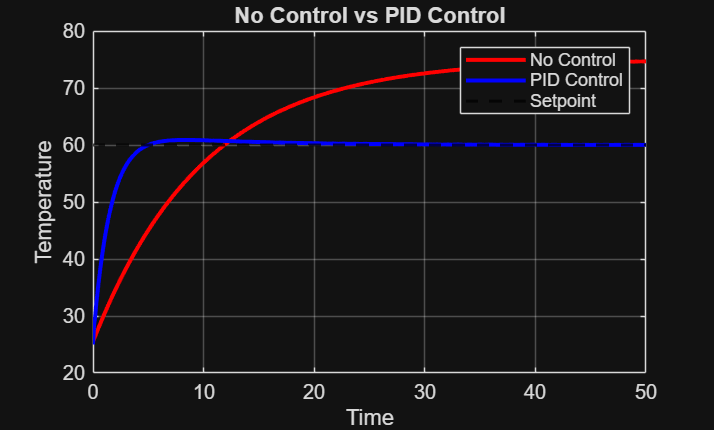


plot(time,temps_no_control, 'r','LineWidth', 2)
hold on
plot(time,temps_pid, 'b','LineWidth', 2)
yline(setpoint, '--k','LineWidth', 1.5)
xlabel('Time')
ylabel('Temperature')
title('No Control vs PID Control')
legend('No Control', 'PID Control', 'Setpoint')
grid on